# Recursive Moving Average Filter

[YouTube](https://www.youtube.com/watch?v=HCd-leV8OkU&t=825s)

clear all
addpath(genpath('D:\OneDrive\MATLAB_FILES\UsefulFunctions'));
load SonarAlt.mat
% edit MovingAvgFilter.mlx

## Example

Smoothing Sonar Altitude Data

Nsamples = numel(sonarAlt);

dt = 0.02;
t = (0:dt:dt*(Nsamples-1))';

xk_Vec = zeros(Nsamples,1);
avg_Vec = zeros(Nsamples,1);
lpf_Vec = zeros(Nsamples,1);

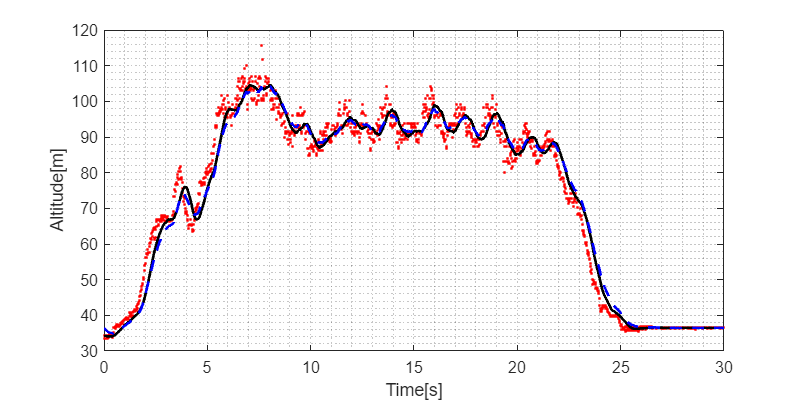

n = 30;
alpha = 0.95;
clear GetSonar MovingAvgFilter

for k = 1:Nsamples
    xk_Vec(k) = GetSonar();
    avg_Vec(k) = MovingAvgFilter(xk_Vec(k), n);
    lpf_Vec(k) = LowPassFilter(xk_Vec(k), alpha);
end

figure('Position',[0 0 800 400])
plot(t, xk_Vec, 'r.', 'LineWidth',1.5,'DisplayName','Measurement'); hold on;
plot(t, avg_Vec, 'k-','LineWidth',2,'DisplayName','MovingAverage');
plot(t, lpf_Vec, 'b--','LineWidth',2,'DisplayName','1st Order LPF');
xlabel('Time[s]')
ylabel('Altitude[m]')
grid minor
set(gca, 'Fontsize', 12)

## Increase in n produce a Delay in estimations - there is better way-- low pass filter